## Оценка параметров реального привода по данным из csv файла 

### Читаем CSV файл

clear; clc;
%test 1 with delay 9ms dt~12ms, little delay in w in comparision to u
% csv = readmatrix("csv/new_test.csv");
% csv = readmatrix("csv/test.csv");
% csv = readmatrix("csv/sin_chi_dt10_floor.csv");
% csv = readmatrix("csv/test_chi.csv");
% csv = readmatrix("csv/sin_chi.csv");
csv = readmatrix("csv/chi_sin_stall_test.csv");

crop = 10;
data_length = length(csv(:,2))-1 - crop

data_length = 1563

time = csv(2:data_length+1, 2);    % мкс
% q_orig = csv(2:data_length+1, 3) * pi/180;  % рад
% w_orig = csv(2:data_length+1, 4) * pi/180;  % рад/c
% dw_orig = csv(2:data_length+1, 5) * pi/180;  % рад/c^2
input = csv(2:data_length+1, 6) / 100 * 6;    % В
current = csv(2:data_length+1, 7);  % А

q_orig = csv(2:data_length+1, 3);  % рад
w_orig = csv(2:data_length+1, 4);  % рад/c
dw_orig = csv(2:data_length+1, 5);  % рад/c^2

t_start = time(1);
time = (time - t_start)/1000000;    % с
tf = time(data_length);

dt_sum = 0;
for k = 2:data_length
    dt = time(k) - time(k-1);
    dt_sum = dt_sum + dt;
end

dt = dt_sum/(data_length-1)

dt = 0.0096


w_orig = smooth(w_orig, 6);
dw_orig = smooth(dw_orig, 20);
current = smooth(current, 6);

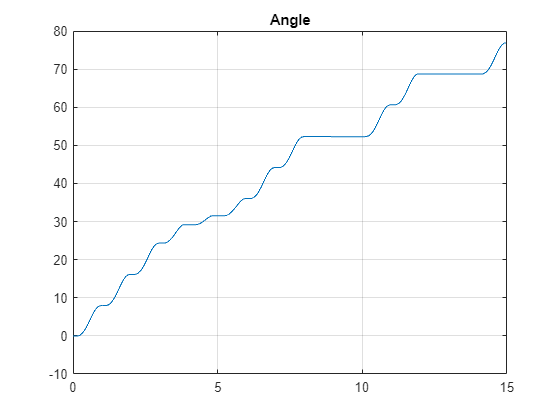

figure;
plot(time, q_orig)
title("Angle")
xlim("auto")
ylim("auto")
grid on

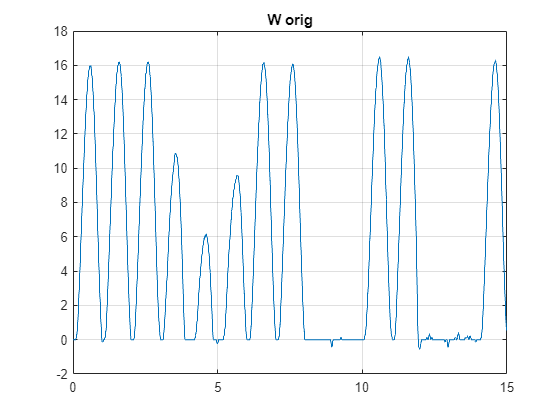


figure;
plot(time, w_orig)
title("W orig")
xlim("auto")
ylim("auto")
grid on

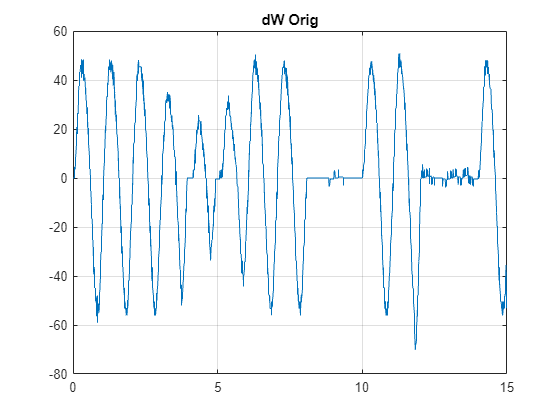


figure;
plot(time, dw_orig)
title("dW Orig")
xlim("auto")
ylim("auto")
grid on

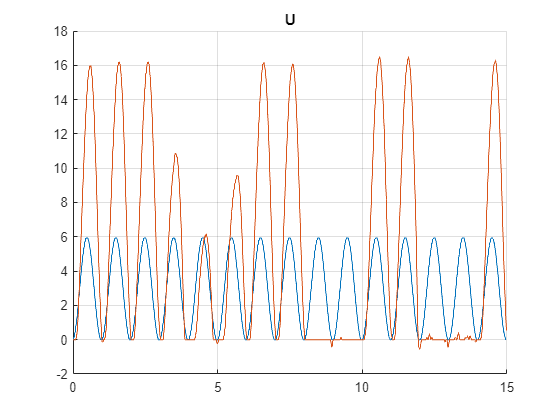


figure;
hold on
plot(time, input)
plot(time, w_orig)
hold off
title("U")
xlim("auto")
ylim("auto")
grid on

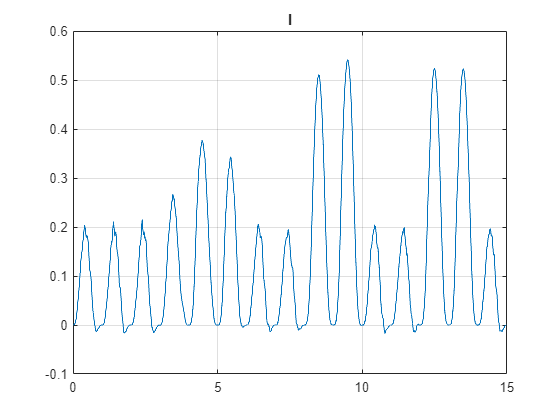


figure;
plot(time, current)
title("I")
xlim("auto")
ylim("auto")
grid on

% start = 3500;
% finish = 3550;

start = 1;
finish = 50;

figure;
plot(time(start:finish), q_orig(start:finish), '*-')
% plot(time(start:finish), ticks(start:finish))
title("Q")
xlim("auto")
ylim("auto")
grid on

figure;
plot(time(start:finish), w_orig(start:finish), '*-')
title("W")
xlim("auto")
ylim("auto")
grid on

figure;
plot(time(start:finish), dw_orig(start:finish), '*-')
title("B")
xlim("auto")
ylim("auto")
grid on

figure;
% plot(time(start:finish), current(start:finish), '*-')
plot(time(start:finish), current(start:finish))
title("I")
xlim("auto")
ylim("auto")
grid on

figure;
hold on
% plot(time(start:finish), input(start:finish), '*-')
plot(time(start:finish), input(start:finish))
plot(time(start:finish), w_orig(start:finish))
hold off
title("U")
xlim("auto")
ylim("auto")
grid on

### Parameters identification with kalman filter model with load

% from offline parameter identification with KF MAXON
L = 1.0551;
R = 5.9043;
Kw = 1.9437;
Km = 1.9437;
J = 0.0085;
Lam = 0.0020;

% from offline parameter identification CHI
L = 0.0876;
R = 19.5747;
Kw = 0.2254;
Km = 0.2254;
J = 0.0004;
Lam = 0.0021; 

% from offline parameter identification CHI + KF (better)
L = 0.0241;
R = 19.7430;
Kw = 0.2203;
Km = 0.2203;
% J = 0.0005;
J = 0.5*0.04727*(0.068/2)^2; % from mass and radius of wheel
Lam = 0.0019; 

% from offline step test
R = 11.8227;
Kw = 0.2923;
Km = Kw;
Lam = 0.0019; 
Mext = -12.3e-3;
    
% random
% L = rand();
% R = rand();
% Kw = rand();
% Km = rand();
% J = rand();
% Lam = rand();

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L];
B = [1/J 0;
     0   Km/(J*L);
     0   1/L];
C = eye(3);
D = [0 0 0]';

C_lqe = [1 0 0;
         0 1 0;
         0 0 0];
[Te, De] = eig(A);
% Cc = ctrb(A,B)
% Cob = obsv(A, C_lqe)
% rank(Cc)
% rank(Cob)

Vd_w = 1e2;
Vd_dw = 1e3;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [1e1 0 0;
      0 1e4 0;
      0 0 1];

% dt = 0.01
dt

dt = 0.0100

[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, dt);
Kf

Kf =     0.4017   -0.0014         0
   -1.4343    0.9886         0
   -0.0006    0.0000         0


% "<< " + Kf(1,1) + ", " + Kf(1,2) + ", " + Kf(1,3) + ", " ...
%       + Kf(2,1) + ", " + Kf(2,2) + ", " + Kf(3,3) + ", " ...
%       + Kf(3,1) + ", " + Kf(3,2) + ", " + Kf(3,3)

betta = 0.3; % коэффициент регуляризации
k0 = 2; % начальное значение матрицы коэффициентов
% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов
I = eye(3); % диагональная единичная матрица
GAMMA_0 = k0.*I; % матрица начальных значений коэффициентов
% GAMMA_0(3,3) = 50;

Th_hat = [0; 0; 0];
Th_hat(1) = L;
Th_hat(2) = J;
Th_hat(3) = Mext;
Th_hat;
Th_hat_start = Th_hat

Th_hat_start =     0.0241
    0.0000
   -0.0123


dTh_hat = [0; 0; 0];

G_hat = GAMMA_0

G_hat =      2     0     0
     0     2     0
     0     0     2


dG_hat = zeros(3, 3);

% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext_arr = zeros(1, data_length);
Mext_arr(1) = Mext;

At = expm(A*dt);
Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B;
Bt = real(Bt);
A_hat = (At-Kf*C_lqe);
B_hat = [Bt Kf];
% "<< " + At(1,1) + ", " + At(1,2) + ", " + At(1,3) + ", " ...
%       + At(2,1) + ", " + At(2,2) + ", " + At(3,3) + ", " ...
%       + At(3,1) + ", " + At(3,2) + ", " + At(3,3)
% "<< " + Bt(1,1) + ", " + Bt(1,2) + ", " ...
%       + Bt(2,1) + ", " + Bt(2,2) + ", " ...
%       + Bt(3,1) + ", " + Bt(3,2)

k_di = 0.9;
Mext_sum = 0;
% Mext = 7e-3;

% for k = 2:20
for k = 2:data_length
    dt = time(k) - time(k-1);
    u_act = input(k-1);

    u = [Mext input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
%     u = [0 input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    
    w_act = x_arr(1, k-1);
    dw_act = x_arr(2, k-1);
    I_act = x_arr(3, k-1);
    dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;

%     w_act = w_orig(k-1);
%     dw_act = dw_orig(k-1);
%     I_act = current(k-1);
%     dI_act = (current(k)-current(k-1))/dt;

    dI_arr(k) = dI_arr(k-1)*(1-k_di) + k_di*dI_act;
    q_arr(k) = q_arr(k-1) + w_act*dt;

%     Mext = Th_hat(4)*x_arr(2, k) + Th_hat(5)*x_arr(1,k) - Th_hat(3)*x_arr(3,k);
%     Mext = -J*x_arr(2, k) - Lam*x_arr(1,k) + Th_hat(3)*x_arr(3,k);
%     Mext = -Th_hat(4)*dw_act - Th_hat(5)*w_act + Th_hat(3)*I_act;
%     Mext = 1.95e-3;
%     Mext_arr(k) = real(Mext);
%     Mext_sum = Mext_sum + Mext;

    phi = [dI_act 0;
           0  dw_act;
           0  -1];
     phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

%     U = [u_act; 0];
    U = [u_act-Kw*w_act; Km*I_act-Lam*w_act];

    Aa = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Aa;   
    Th_hat = Th_hat + dTh_hat * dt; 

    Mext = Th_hat(3);
    Mext_arr(k) = real(Mext);
end

Mext_avr = Mext_sum/data_length

Mext_avr = 0


Th_hat_start

Th_hat_start =     0.0241
    0.0000
   -0.0123


Th_hat

Th_hat =    NaN
   NaN
   NaN


eL = Th_hat(1)

eL = NaN

eR = R

eR = 11.8227

eKw = Kw

eKw = 0.2923

eKm = Km

eKm = 0.2923

eJ = Th_hat(2)

eJ = NaN

eLam = Lam

eLam = 0.0019

eMext = Th_hat(3)

eMext = NaN

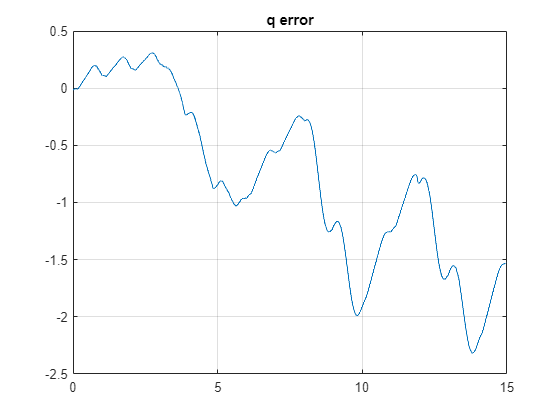

start = 1;
% finish = 500;
finish = data_length;

figure
plot(time(start:finish), (q_orig(start:finish)'-real(q_arr(start:finish))))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

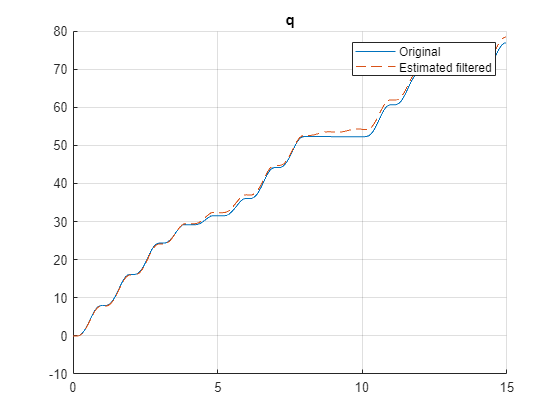


% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time(start:finish), q_orig(start:finish))
plot(time(start:finish), q_arr(start:finish), "--")
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

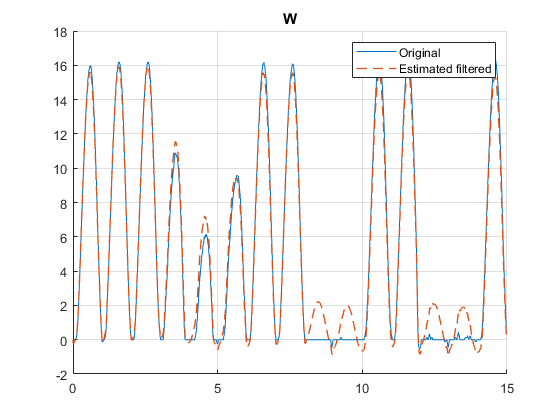


figure
hold on
plot(time(start:finish), w_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 1, "LineStyle", "--")
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

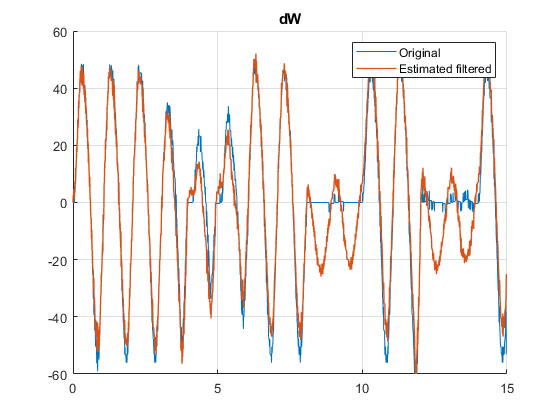


figure
hold on
plot(time(start:finish), dw_orig(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 1)
hold off
grid on
title("dW")
xlim("auto")
% ylim("auto")
ylim([-60 60])
legend("Original", "Estimated filtered")

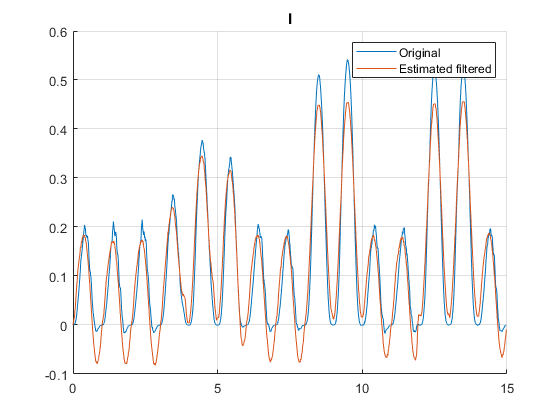


figure
hold on
plot(time(start:finish), current(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

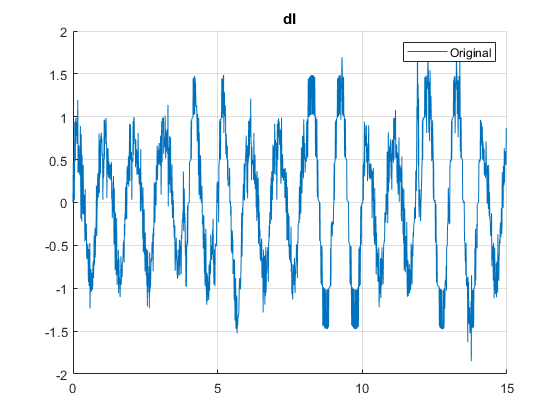


figure
hold on
plot(time(start:finish), dI_arr(start:finish))
hold off
grid on
title("dI")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

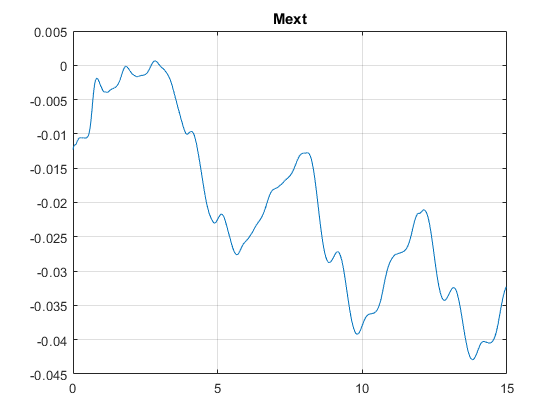


figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")

Ah = [-eLam/eJ eKm/eJ; -eKw/eL -eR/eL];
Bh = [-1/eJ 0; 0 1/eL];
C = [1 0; 0 1];
D = [0 0; 0 0];

A;
A = Ah
B;
B = Bh

Amp = 3;
Bias = 3;
W = 1;
fi = 3.1415;
Mext = 6e-3;

Const_input = [Amp Bias W fi Mext];

out1 = sim('motor_model_sim.slx', tf);
o = out1.simout;

figure
hold on
plot(time, q_orig)
plot(o.q)
hold off
grid on
title("q")
legend("Original", "Model")

figure
hold on
plot(time, w_orig)
plot(o.w)
hold off
grid on
title("w")

figure
hold on
plot(time, dw_orig)
plot(o.dw)
hold off
grid on
title("dw")

figure
hold on
plot(time, current)
plot(o.I)
hold off
grid on
title("I")

figure
hold on
plot(time, dI_arr)
plot(o.dI)
hold off
grid on
title("dI")